close all
clear, clf

addpath(genpath('RangeCamera\'))

**3 Theory questions about the range camera lab setup This lab setup is demonstrated in the video RangeCameraLabSetup.mp4. Look at the video and answer the following questions. **

**QUESTION 1: Which figure among Fig. 2.4-2.8 in [1] corresponds to the range camera lab setup? **

Arrangement 4, figure 2.7

**QUESTION 2: Give an approximate value for α of the range camera lab setup. **

About 60 degrees

**QUESTION 3: Give an approximate value for the desired β by looking in table 3. Suppose that 18mm ≤ f ≤ 75mm. **

Between 2.67 and 2.81 degrees

**QUESTION 4: The range camera lab setup has a sensor that is perpendicular to the optical axis, ie. β = 0. What is the consequence when β not equals the desired value? **

The schempflug condition is not fulfilled so some parts of the image will be out of focus

**QUESTION 5: How serious is the β discrepancy in our case? **

Since the optical axis is relatively large it is not very detremental

**QUESTION 6: Which equations are valid for r and y in the range camera lab setup? (Give only the equation numbers.)**

Eq .2.15 and 2.21

## 4 Basic images from the range camera lab setup

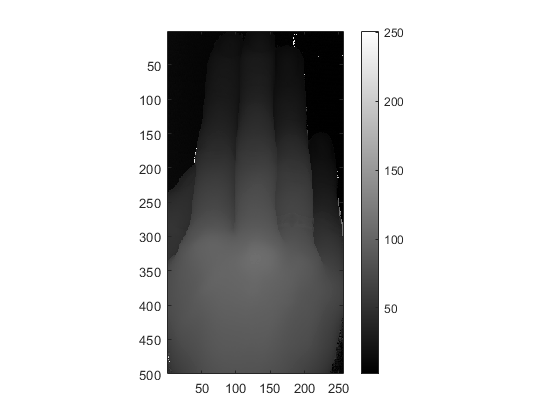

fp = fopen('handran','r');
a = fscanf(fp,'%d',[500,256]); % image size: 500*256
figure(1)
imagesc(a);
axis image; colorbar;
colormap([(0:255)'/255,(0:255)'/255,(0:255)'/255])

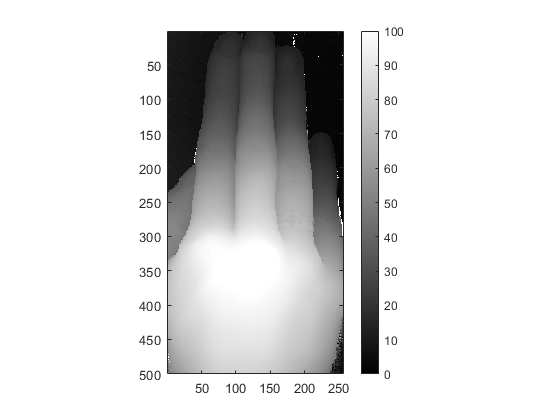

imagesc(a,[0,100]);
axis image; colorbar;

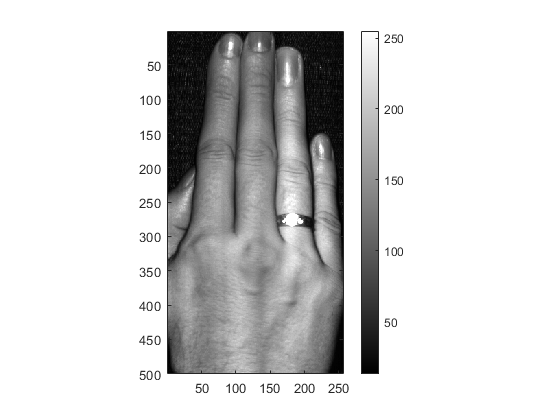



fp = fopen('handint','r');
b = fscanf(fp,'%d',[500,256]); % image size: 500*256
figure(2)
imagesc(b);
axis image; colorbar;
colormap([(0:255)'/255,(0:255)'/255,(0:255)'/255])

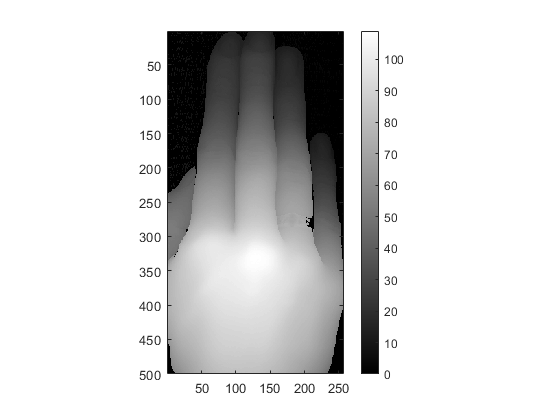


T = 35;

figure(3);
c = a.*(b>T);
imagesc(c);
axis image; colorbar;
colormap gray

**QUESTION 7: Determine a suitable value for T above!**

T = 35

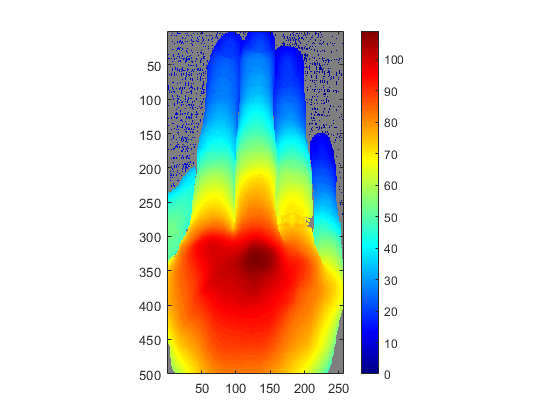

rainbow = jet;
rainbow(1,:) = 1/2*[1,1,1]; % Question 8
colormap(rainbow)

**QUESTION 8: The values that we set to 0 before should rather be marked as uncertain. Perform this by changing the colortable so that the uncertain values are shown in gray. What commands do you give?**

Check cell above.

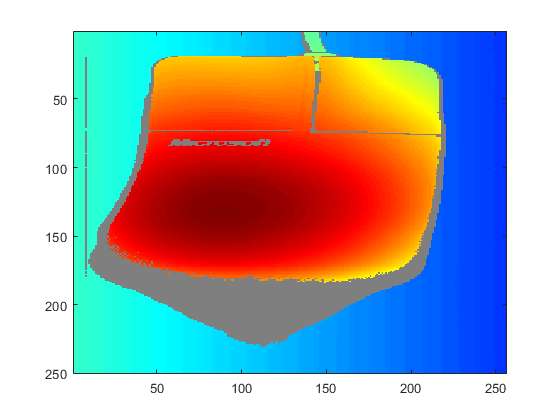

fp=fopen('musran','r');
b = fscanf(fp,'%d',[250,256]); % image size: 250*256
imagesc(b);

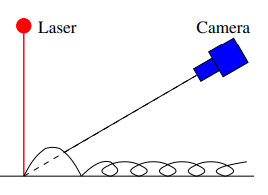

**QUESTION 9: What type of occlusion is this?**

Sensor occlusion

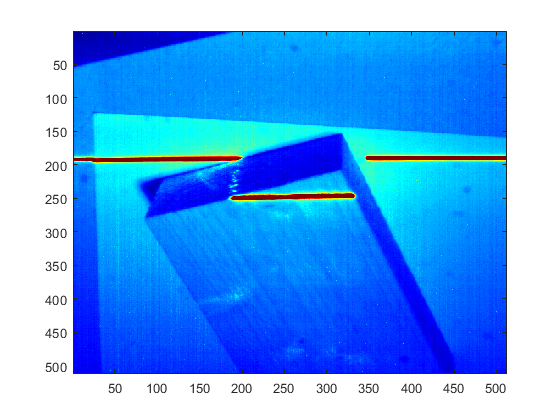

fp = fopen('wood','r');
g = fscanf(fp,'%d',[512,512]); % image size: 512*512
imagesc(g);

**QUESTION 10: The simplest method is to look for the maximum value along every row/column of the image. Your goal is to plot the profile SL(x = const, t). Use the MATLAB-commands [maxint, maxindex] = max(x,[],dim) and plot. Give your MATLAB-commands and sketch the profile below. **

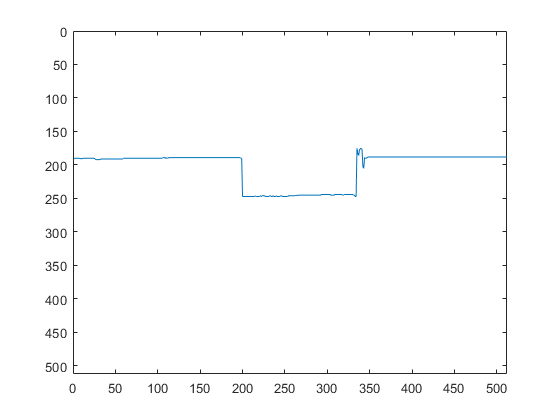

[maxint, maxindex] = max(g,[],1);
plot(maxindex)
xlim([0, 512])
ylim([0, 512])
axis ij

**QUESTION 11: How can you locate the uncertain values? **

Thresholding the from intensity in maxint.

**QUESTION 12: By using the information in maxint, tidy up the profile by setting some of the values to uncertain, NaN (not a number). Give your commands below: **

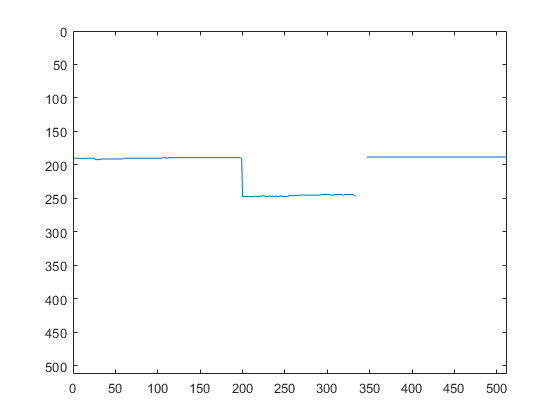

maxindex(maxint<250) = NaN;
plot(maxindex);
xlim([0, 512])
ylim([0, 512])
axis ij

## 5 Calibration of the range camera lab setup 

**QUESTION 13: Rehearse the exercise regarding calibration of a flat world, a homography, in the laboratory assignment regarding camera calibration. At the computer exercise you will do a similar calibration task, but then the flat world will be the laser sheet. How many points on a real calibration object inserted in the laser sheet (ri , yi) is nescessary to measure?**

We need to determine the camera matrix C which needs 4 point correspondences to solve the 8 variables uniquely.

**QUESTION 14: For your help there is a non-completed MATLAB code in /courses/TSBB09/RangeCamera/calibration.m. See also the MATLAB section in the end this laboratory assignment. Make a sketch of the calibration object in the utility box and the correponding calibration points (Y 1, R1),(Y 2, R2), ...,(Y 8, R8) in calibration.m.**  

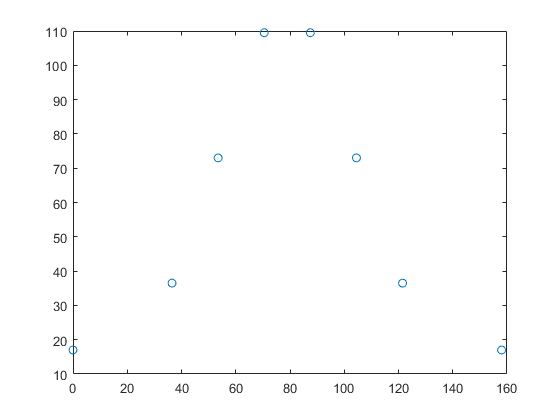

y = [0, 36.5, 53.5, 70.5, 87.5, 104.5, 121.5, 158];
r = [17 36.5 73 109.5 109.5 73 36.5 17];
figure
plot(y, r, 'o')

**QUESTION 15: Measure corresponding points in the calibration image calim.**

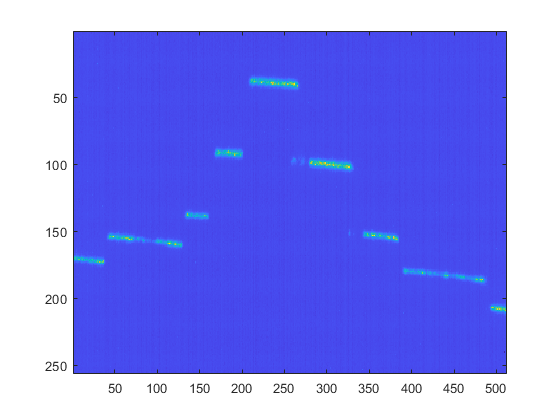

load 'calim'
imagesc(calim)

u1 = 45; v1 = 154;

u2 = 136; v2 = 138;

u3 = 171; v3 = 91;

u4 = 213; v4 = 38;

u5 = 263; v5 = 41;

u6 = 327; v6 = 102;

u7 = 382; v7 = 156;

u8 = 484; v8 = 185;

calibration

C =     2.6745   -0.6320   54.2924
    0.1800   -1.4258  174.7843
   -0.0001   -0.0015    1.0000


test =    44.7229
  154.6026
    0.9738


**QUESTION 16: Compute and give the calibration matrix C.**

`C = ``3×3`

`    2.6745   -0.6320   54.2924`

`    0.1800   -1.4258  174.7843`

`   -0.0001   -0.0015    1.0000`

**QUESTION 17: Check your C-matrix by transforming (Y 1, R1) = (0, 17).**

`   44.7229`

`  154.6026`

**QUESTION 18: The test object is a box with a parallel trapezoidal crosssection. Your task is to measure the circumference of it. Use the image trapez and maybe also the image notrapez. Compare your computed value with a measure of the real test object. You should get a good agreement with error < 5%.**

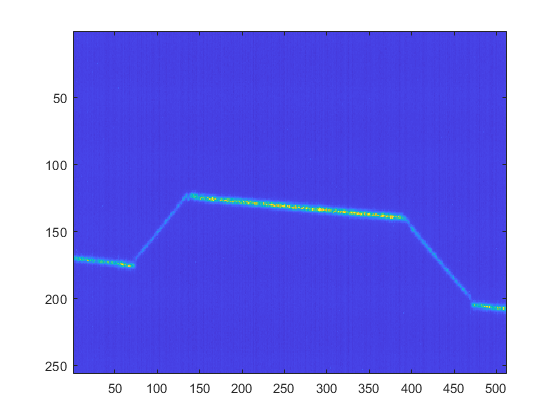

load 'trapez.mat'
load 'notrapez.mat'
imagesc(trapez)

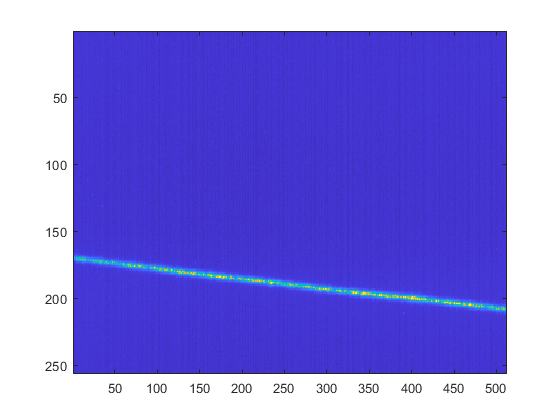

imagesc(notrapez)


u = [70 136 391 471];
v = [175 124 140 203];
p_hom = [u; v; ones(1,length(u))];

trap = inv(C) * p_hom;
trap = [trap(1,:)./trap(3,:); trap(2,:)./trap(3,:); trap(3,:)./trap(3,:)]

trap =     6.0219   37.8175  125.0970  153.8107
    0.8168   46.9283   48.4089    1.5401
    1.0000    1.0000    1.0000    1.0000


trapeuc = trap(1:2,:)'

trapeuc =     6.0219    0.8168
   37.8175   46.9283
  125.0970   48.4089
  153.8107    1.5401


dist = squareform(pdist(trapeuc))

dist =          0   56.0110  128.2338  147.7907
   56.0110         0   87.2920  124.5572
  128.2338   87.2920         0   54.9651
  147.7907  124.5572   54.9651         0


trap_circum = dist(1,2)+dist(2,3)+dist(3,4)+dist(1,4)

trap_circum = 346.0588

The circumference is approx 346mm compared to the measured 347mm.

## 6 Measures with an industrial range camera

**QUESTION 19: From the figure above we can see that each range “pixel” will cover a different area on the object dependent on the distance to the sensor. Based on this information, where in the volume will we have the most accurate measurements? **

We will have higher pixel resolution the closer the object is so as close as possible in the total height range.

load cardim;
rangeim

rangeim = struct with fields:
      range: [141×191 single]
          x: [141×191 single]
     status: [1×191 int32]
    encoder: [1×191 int32]
    prof_id: [1×191 int32]


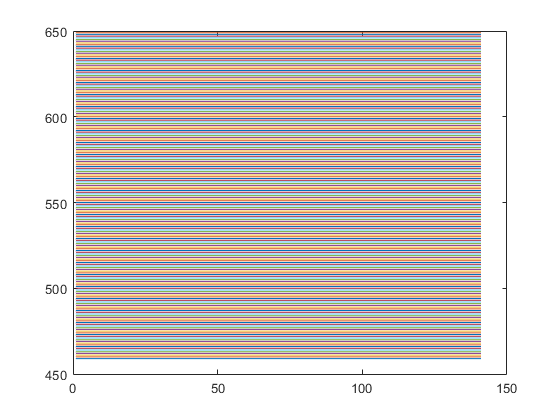


tick_divide = 1;
r = rangeim.range;
y = rangeim.x;
x = repmat(double(rangeim.prof_id)/tick_divide,[size(y,1),1]);
imsz = size(r);
R1 = zeros([imsz 3]);
R1(:,:,1) = double(y);
R1(:,:,2) = double(x);
R1(:,:,3) = double(r);
cert = (r == 0);
R1c = repmat(cert,[1 1 3]);
R1(R1c) = NaN;

plot(x)

**QUESTION 20: Regard the following row, x = repmat(double(rangeim.prof id)/tick divide,... where rangeim.prof id is a 1D integer linear scale and tick divide is a scaling factor. Print x in the MATLAB window and check if it is a linear scale in the row-direction, column-direction or both! **

Linear scale in the row-direction

**QUESTION 21: Why is it appropriate with a linear scale for x?**

Because of how the camera is set up we need to scale each line appropriately to get the correct geometry.

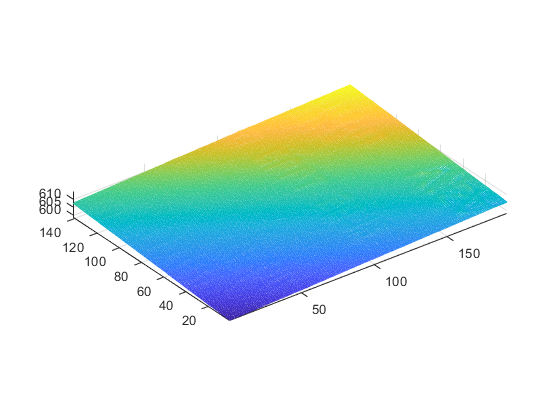

mesh(R1(:,:,3)); axis equal

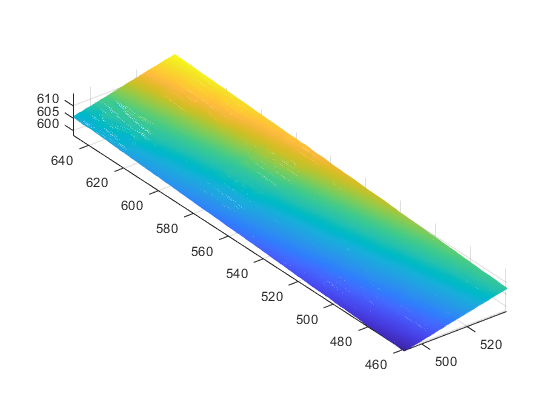

mesh(R1(:,:,1),R1(:,:,2),R1(:,:,3)); axis equal

**QUESTION 22: Load your range data into the variable R1 and try both: mesh(R1(:,:,3)); axis equal mesh(R1(:,:,1),R1(:,:,2),R1(:,:,3)); axis equal Which one is theoretically the best?**

The second one

**QUESTION 23: Adjust tick divide so that you can read parts of the text. Try e.g. 1, 2, 3, 4, 5. What is a good value for tick divide? Write down parts of the text! **

Easy to read VISA and the numbers 0661 5578. Could not see much difference in different tick divides

**QUESTION 24: Why do you need to adjust tick divide if the camera is calibrated?**

We dont know how fast it was scanned in x 

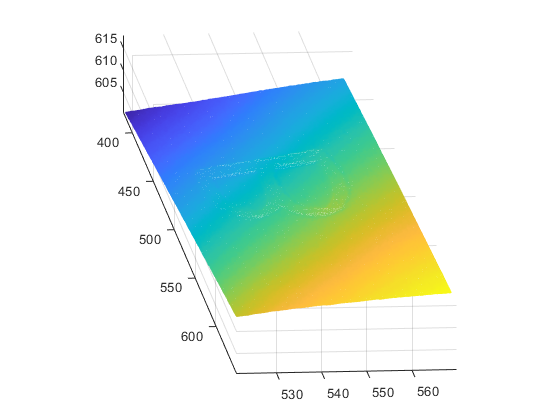

load letter.mat;

tick_divide = 1;
r = rangeim.range;
y = rangeim.x;
x = repmat(double(rangeim.prof_id)/tick_divide,[size(y,1),1]);
imsz = size(r);
R1 = zeros([imsz 3]);
R1(:,:,1) = double(y);
R1(:,:,2) = double(x);
R1(:,:,3) = double(r);
cert = (r == 0);
R1c = repmat(cert,[1 1 3]);
R1(R1c) = NaN;

mesh(R1(:,:,1),R1(:,:,2),R1(:,:,3)); axis equal

**QUESTION 25: Which letter is found in the range scan?**

B

**QUESTION 26: Look in the utility box for the object that was input to the ruler. Do you agree that there is absolutely no height difference at all between the letter and its background?**

There is apparently a height difference.

**QUESTION 27: Explain why there is a height difference! **

**depends on reflectivity**

## 6.6 Volume measurement of object

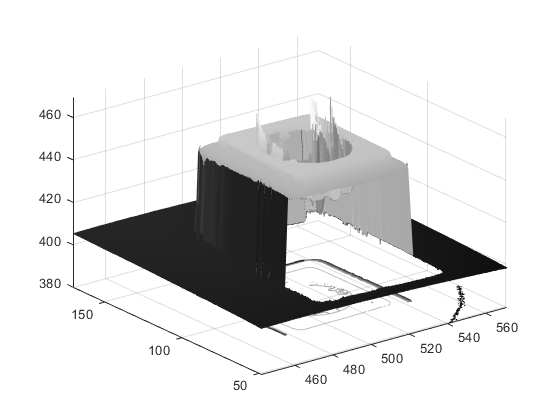

load vit_vaggkontakt;

tick_divide = 4.0938;
r = rangeim.range;
y = rangeim.x;
x = repmat(double(rangeim.prof_id)/tick_divide,[size(y,1),1]);
imsz = size(r);
R1 = zeros([imsz 3]);
R1(:,:,1) = double(y);
R1(:,:,2) = double(x);
R1(:,:,3) = double(r);
cert = (r == 0);
R1c = repmat(cert,[1 1 3]);
R1(R1c) = NaN;

% crop
R2 = R1(401:700,201:700,:);
Intens = rangeim.intens(401:700,201:700);
figure(1)
meshc(R2(:,:,1),R2(:,:,2),R2(:,:,3))

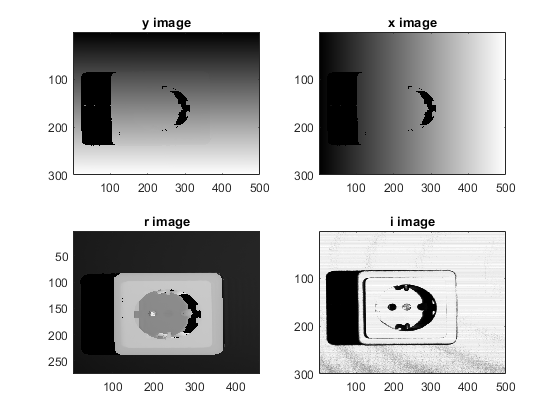

figure(2)
subplot(2,2,1), imagesc(R2(:,:,1)), title('y image');
subplot(2,2,2), imagesc(R2(:,:,2)), title('x image');
subplot(2,2,3), imagesc(R2(:,:,3)), title('r image');
subplot(2,2,4), imagesc(Intens(:,:)), title('i image');

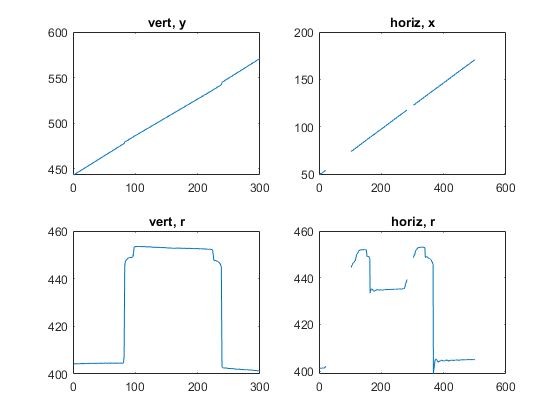

figure(3)
subplot(2,2,1), plot(R2(:,320,1)), title('vert, y');
subplot(2,2,2), plot(R2(150,:,2)), title('horiz, x');
subplot(2,2,3), plot(R2(:,320,3)), title('vert, r');
subplot(2,2,4), plot(R2(150,:,3)), title('horiz, r');

**QUESTION 28: Where are the distortions and what is the reason for them?**

They come from occlusion (and metal shiny parts)

**QUESTION 29: How can the distortions be detected and “removed” (marked with NaN)?**

By thresholding like we did before

**QUESTION 30: What is the width of the real wall socket?**

64mm x 64mm

**QUESTION 31: What is the width of the wall socket in the y-direction in mm according to the MATLAB figures (2) and/or (3)? (You need to click in the figures and check the values.) Does the measurement agree with the real measure? **

y direction 64mm

**QUESTION 32: What is the width of the wall socket in the x-direction in pixels according to the MATLAB figures (2) and/or (3)? (You need to click in the figures and check the values.) Use this information to determine a new value for tick divide! This value is important since you will need it in the next task. Let the teacher check the value!**

263 pixels in x direction and 154 in y direction

tick_divide = 262/64 gives correct values

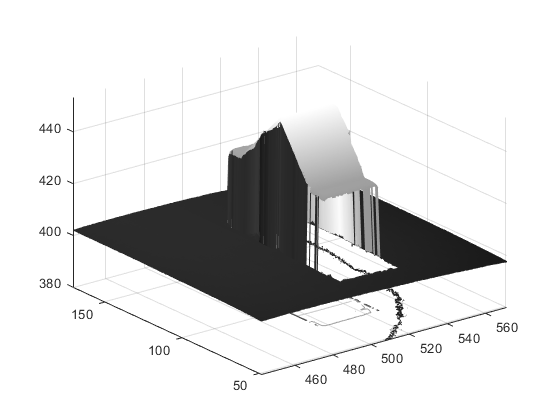

load('hus0.mat')

rangeim;
tick_divide = 4.0938;
r = rangeim.range;
y = rangeim.x;
x = repmat(double(rangeim.prof_id)/tick_divide,[size(y,1) 1]);
imsz = size(r);
R1 = zeros([imsz 3]);
R1(:,:,1) = double(y);
R1(:,:,2) = double(x);
R1(:,:,3) = double(r);
cert = (r == 0);
R1c = repmat(cert,[1 1 3]);
R1(R1c) = NaN;


R2 = R1(401:700,201:700,:);
Intens = rangeim.intens(401:700,201:700);
figure(1)
meshc(R2(:,:,1),R2(:,:,2),R2(:,:,3))

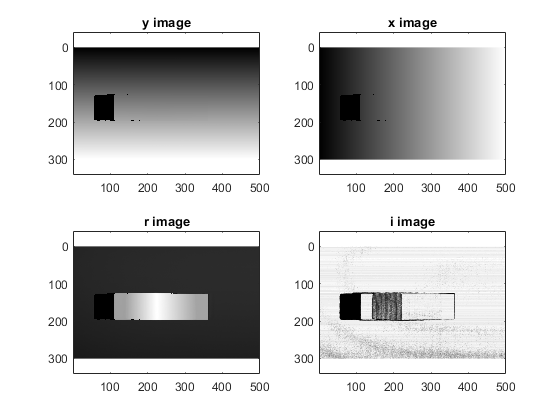

figure(2)
subplot(2,2,1), imagesc(R2(:,:,1)), title('y image'); axis equal
subplot(2,2,2), imagesc(R2(:,:,2)), title('x image');axis equal
subplot(2,2,3), imagesc(R2(:,:,3)), title('r image');axis equal
subplot(2,2,4), imagesc(Intens(:,:)), title('i image');axis equal

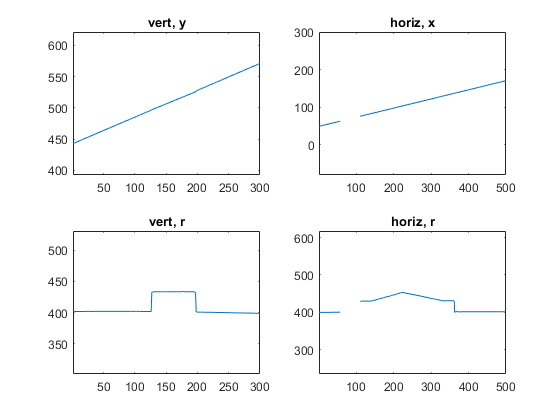

figure(3)
subplot(2,2,1), plot(R2(:,320,1)), title('vert, y');axis equal
subplot(2,2,2), plot(R2(150,:,2)), title('horiz, x');axis equal
subplot(2,2,3), plot(R2(:,320,3)), title('vert, r');axis equal
subplot(2,2,4), plot(R2(150,:,3)), title('horiz, r');axis equal

**QUESTION 33: The value for ∆x is the same for all volume elements, but the value for ∆y varies. Why? Hint: Check the last figure in Section 6.2.**

We get higher pixel density the closer the object comes to the camera.

**To calculate the volume, start by cropping and showing the data as you did for the white wall socket. The MATLAB commands diff and nansum will be useful. **

x_delt = 1/tick_divide; %mm per pixel scaler
y_delt = [diff(R2(:,:,1));zeros(1,500)]; %y scaler

volume = sum(nansum((R2(:,:,3)-402).*(R2(:,:,3)>410).*y_delt*x_delt)) %

volume = 7.0290e+04

**QUESTION 34: Which volume do you get for hus0? **

`volume = 7.0290e+04`

**QUESTION 35: Check 1: Take the other scan, hus90, and check so that you get approximately the same volume. Which volume do you get now? **

`volume = 6.9231e+04`

**QUESTION 36: Check 2: Measure the volume of the real red house with a ruler!**

60*30*30+30*33*30/2

ans = 68850